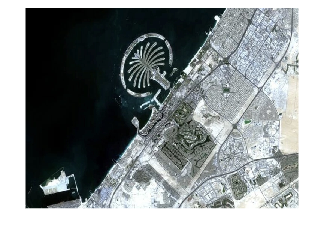

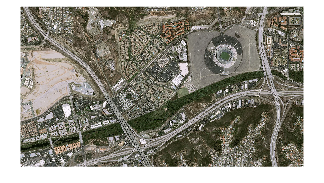

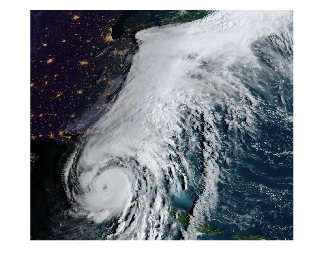

clear all 
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%  Important params  %%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
snipsPerRow = 0;
numSnips = 0;
snipDims = [300, 300];
overlap = 100;
jitter = 100;
stretch = 200;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%  Directory Stuff  %%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
directory = "Test Images/Original/";
imagefiles = dir(directory+"*");      
nfiles = length(imagefiles);    % Number of files found

for ii=4:nfiles
   currentfilename = imagefiles(ii).name;
   currentimage = imread(directory+currentfilename);
   images{ii - 3} = currentimage;
   [~,imageNames{ii - 3},~] = fileparts(currentfilename);
   figure()
   imshow(images{ii - 3});
end


snippedDir = dir("Test Images/Snipped/"); 
rmdir(snippedDir(1).folder,'s')
mkdir(snippedDir(1).folder)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%  Snippage  %%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Circular mask
x = -snipDims(1)/2:snipDims(1)/2;
y = -snipDims(1)/2:snipDims(1)/2;
[xx, yy] = meshgrid(x,y);
snipMask = zeros(size(xx));
snipMask((xx.^2+yy.^2)<(snipDims(1)/2)^2)=1;
snipMask = imresize(snipMask, snipDims+1, 'nearest');

for i=1:length(images)
    mkdir(strcat(snippedDir(1).folder, '/', imageNames{i}));

    % Calculate snips
    snipsPerRow = ceil(size(images{i},2)/(snipDims(2)-overlap))
    snipsPerCol = ceil(size(images{i},1)/(snipDims(1)-overlap))
    numSnips = snipsPerCol*snipsPerRow;

    for j = 1:numSnips
        image = images{i};
        sz = size(image);
        [y, x] = ind2sub([snipsPerCol,snipsPerRow],j);

        % Get bottom-left corner point and check bounds
        windowMax = [(y+1)/(snipsPerCol+1)*sz(1), (x+1)/(snipsPerRow+1)*sz(2)];
        windowMax = [windowMax(1)+jitter*(rand()-0.5),windowMax(2)+jitter*(rand()-0.5)];
        windowMax = min(windowMax,sz(1:2));
        sx = stretch*(rand()-0.5);
        sy = stretch*(rand()-0.5);
        windowMax = max(windowMax,[snipDims(1)+sx+1,snipDims(2)+sy+1]);

        % Snip image
        subimage = image(windowMax(1)-snipDims(1)-sx:windowMax(1), windowMax(2)-snipDims(2)-sy:windowMax(2), :);
        
        % Mask image
        snipMask2 = imresize(snipMask, [snipDims(1)+sx,snipDims(2)+sy], 'nearest');
        subimage = subimage .* cast(snipMask2,"uint8");
        
        % Save image
        imwrite(subimage,strcat(snippedDir(1).folder, '/', imageNames{i}, '/', imageNames{i}, string(j), '.png'));
    end
end

snipsPerRow = 8

snipsPerCol = 6

snipsPerRow = 10

snipsPerCol = 6

snipsPerRow = 6

snipsPerCol = 6